# Processing Data Samples from MRI

## Data Collection

Fs = 60.0;
Duration = 30.0; % Seconds
raw_chest_sample = acquire_radar_data(Fs, Duration);

Drawing the Raw Data

Fs = 60.0;
Duration = 30.0; % Seconds
load("raw_chest_sample.mat");

figure(1);
raw_chest_sample_real = real(raw_chest_sample);
surf(raw_chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
view(2);
xlabel('Range Bin')
ylabel('Samples')
figure(2);

Remoing the offset of the sent information

[slowTime, fastTime] = size(raw_chest_sample);
chest_sample = zeros(slowTime, fastTime);
zero_sample = raw_chest_sample(1,:);
for i=1:slowTime
    chest_sample(i,:) = raw_chest_sample(i,:) - zero_sample;
end
chest_sample_real = real(chest_sample);
surf(chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
xlabel('Fast Time')
ylabel('Slow Time')
view(2);

clear i zero_sample;

% Calculating Respiratory Rate from the 3D plot by finding the lowest point
% at a certain time and find the positions for that lowest time
lowest_time = zeros(slowTime, 0);
lowest_point = zeros(slowTime, 0);
for i = 1:slowTime
   [lowest_point(i), lowest_time(i)] = min(chest_sample_real(i,1:30));
end
plot(real(lowest_point));

Moving Average

hold on;
lowest_point_moving = movmean(lowest_point, 49);
lowest_point_moving_2 = movmean(lowest_point,99);
lowest_point_moving_3 = movmean(lowest_point_moving_2,299);
lowest_point_moving_4 = movmean(lowest_point_moving_3,499);
plot(real(lowest_point_moving));
plot(real(lowest_point_moving_4));
hold off;

Taking the difference between the moving average and the sample

hr_diff = lowest_point - lowest_point_moving;
plot(real(hr_diff));
L = length(hr_diff);

Calculating the overall spectrum

hrfft = fft(hr_diff);
hrfft = abs(hrfft/L);
hrfft = hrfft(1:L/2+1);
f = Fs*(0:(L/2))/L;
stem(f,hrfft) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

[~, hr_index] = max(hrfft);
hr = f(hr_index) * 60;

clear i L lowest_point_moving_2 lowest_point_moving_3 hr_index hr_max;

Shifting the windows to get a rate over time

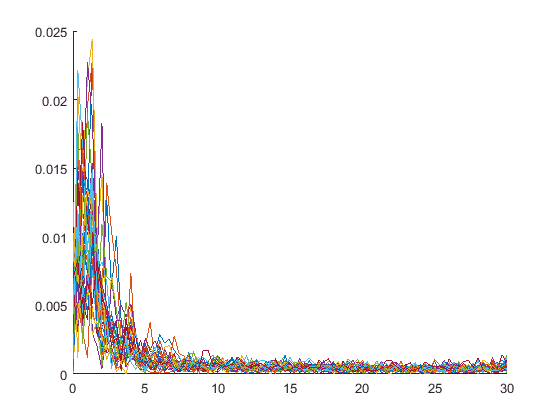

% Need to loop
window_size = 180;
shift_sample_rate = 4;
sample_count = (slowTime - window_size)/window_size * shift_sample_rate;

window = zeros(window_size);
hr_time = zeros(sample_count);

f = Fs*(0:(window_size/2))/window_size;

hold on;
for i=1:sample_count-1
    start = i*window_size/shift_sample_rate;
    finish = i*window_size/shift_sample_rate + window_size;
    window = hr_diff(start:finish);
    
    % Get the FFT
    hrffts = fft(window);
    hrffts = abs(hrffts/window_size);
    hrffts = hrffts(1:window_size/2+1);
    
    stem(f, hrffts);
    hr_time(i) = mean(hrffts.*f);
    % Use the 
    
end
hold off;

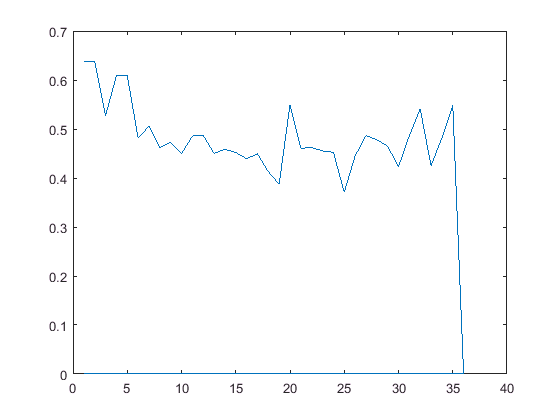

hr_time = hr_time * 60;
plot(hr_time);

Using a Filter

% Using filter
% hrFilter = designfilt('bandpassfir', 'StopbandFrequency1', 0.5, 'PassbandFrequency1', 0.6, 'PassbandFrequency2', 2.0, 'StopbandFrequency2', 2.5, 'StopbandAttenuation1', 60, 'PassbandRipple', 1, 'StopbandAttenuation2', 60, 'SampleRate', 60);
load('hrFilter.mat');
hrFilted = filter(hrFilter, hr_diff);
hold on;
plot(real(hrFilted));
hold off;

## Modelling

% Load the 3D chest sample

% Create a fake 2D chest sample from the 3D sample
chest_model = zeros(30, 30, 30);
chest_model(:,1:1,:) = 1;        % Clothes front
chest_model(:,2:3,:) = 3;        % Skin
chest_model(:,4:5,:) = 2;        % Fat
chest_model(:,6:7,:) = 4;        % Muscle
chest_model(:,8:11,:) = 5;        % Bone
chest_model(:,12:12,:) = 8;        % Fat
chest_model(:,13:14,:) = 9;        % Heart-muscle
chest_model(:,15:18,:) = 5;        % Blood
chest_model(:,19:20,:) = 4;        % Heart-muscle
chest_model(:,21:21,:) = 3;        % Fat
chest_model(:,22:27,:) = 5;        % Lung
chest_model(:,28:28,:) = 2;        % Bone
chest_model(:,29:29,:) = 3;        % Muscle
chest_model(:,30:30,:) = 4;        % Fat
surf(chest_model(:,:,1), 'EdgeColor', 'None');
view(2);
title('Depth of surface')
xlabel('Depth')
ylabel('Medium Type')
